clear
close all



RC circuit

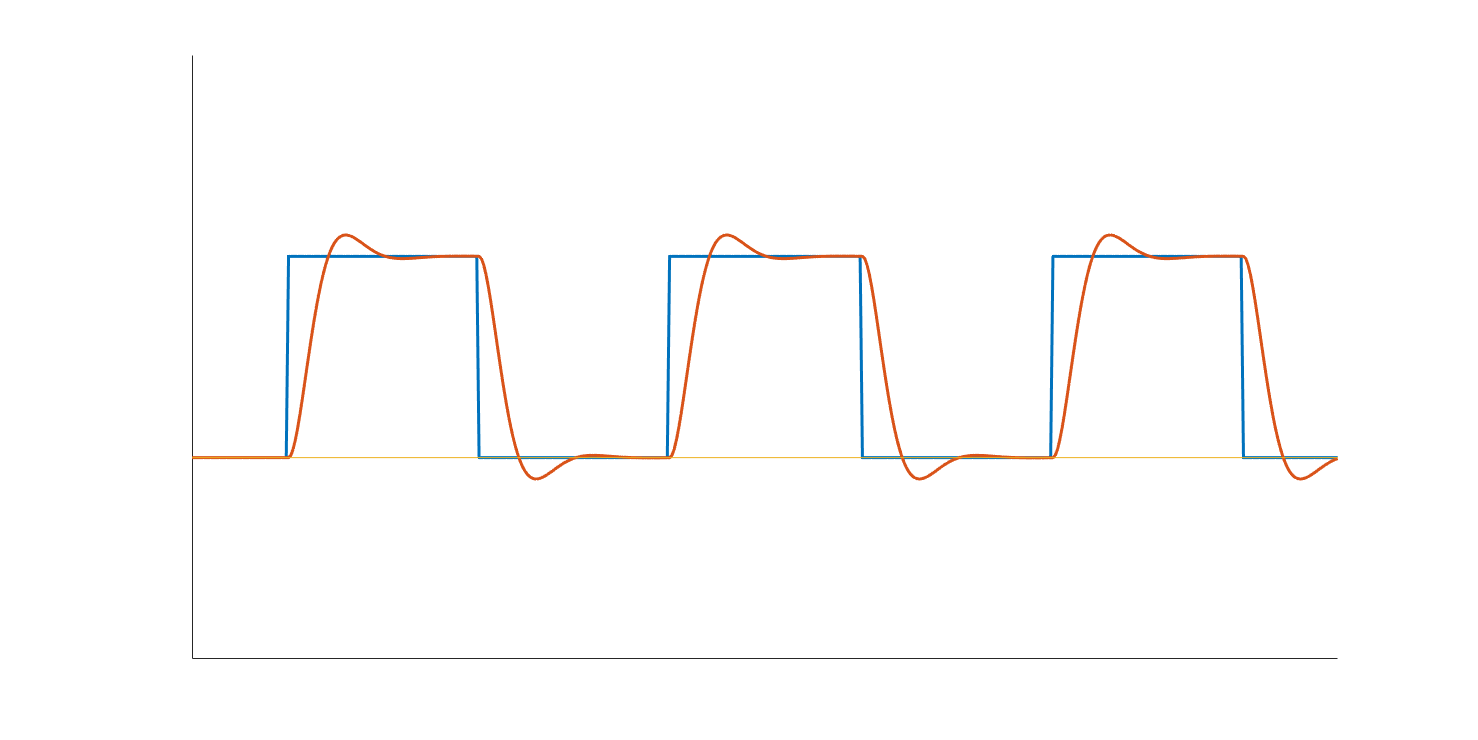

R = 300;
L = 20e-2;
C = 3e-6;

tmax =6e-2;
t = linspace(0,tmax,500);
f = 0.5e2;
V = sin(t*2*pi*f-pi/2)>0;

Vcs = tf(1,[L*C, R*C, 1]);
[Vc,tsim] = lsim(Vcs,V,t);

figure('outerposition',[1,1,1000,500])

plot(t,V,'linewidth',1.5);
hold on
plot(tsim,Vc,'linewidth',1.5);
% plot([0,1],[1,1]*0.6321)
plot([0,1],[1,1]*0)
hold off
box off
axis([0,tmax,-1,2])
xticks([])
yticks([])